# **MATLAB PROJECT: FIRST PART**

Group 2

Our group is composed by:

- Alessia Pazzaglia

- Alessia Bresolin

- Martina Serandrei

- Andrea Magri

## Task 1:

Import the dataset in MATLAB

We have imported data from Excel thanks to the easiest procedure: clicking on *Import Data *in the Home Tab of the main MATLAB window and selecting the file whose data we want to import. Moreover we have also changed the way the data is saved, and so a numeric matrix.

save 'Automobiledata' Automobiledata

## Task 2:

Store the vectors of observations of the response variable and each of the regressors in separate MATLAB variables.

In order to save some variables we write the variable name after the file name

The dependent variable, the variable we want to predict, is "Price", while the other ones are the independent variables

price = Automobiledata(:,5);
len = Automobiledata(:,1);
curb_weight = Automobiledata(:,2);
engine_size = Automobiledata(:,3);
horsepower = Automobiledata(:,4);

## Task 3:

Generate four distinct scatterplots of the response variable vs. each of the regressors.

We have plotted the scatterplots of the four variables thanks to some some built-in functions of matlab.

#### Price vs length

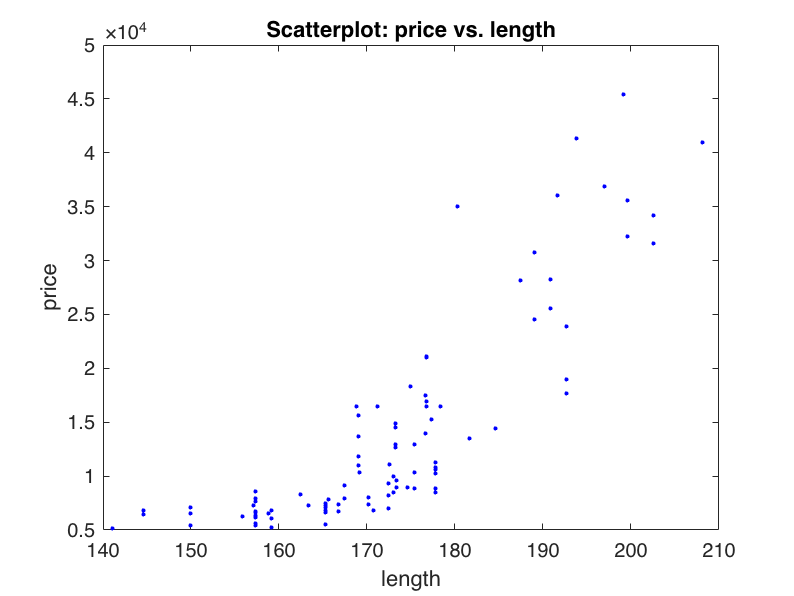

figure()
plot(len, price,'b.')
xlabel('length')
ylabel('price')
title('Scatterplot: price vs. length')

#### Price vs Curb weight

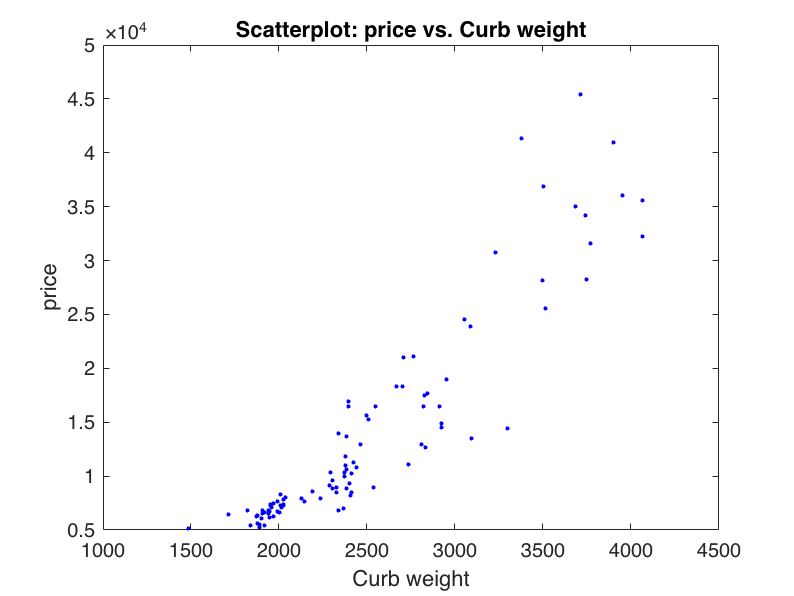

figure()
plot(curb_weight,price,'b.')
xlabel('Curb weight')
ylabel('price')
title('Scatterplot: price vs. Curb weight')

#### Price vs Engine size

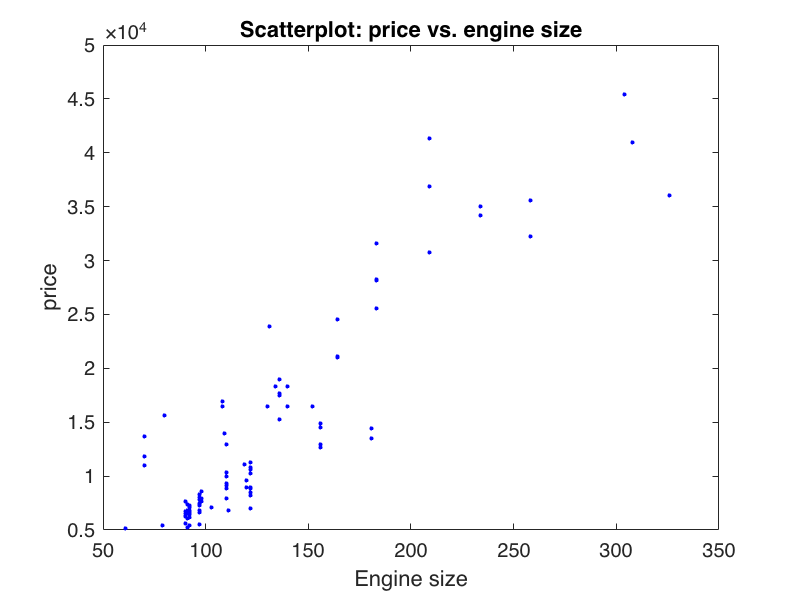

figure()
plot(engine_size,price,'b.')
xlabel('Engine size')
ylabel('price')
title('Scatterplot: price vs. engine size')

#### Price vs Horsepower

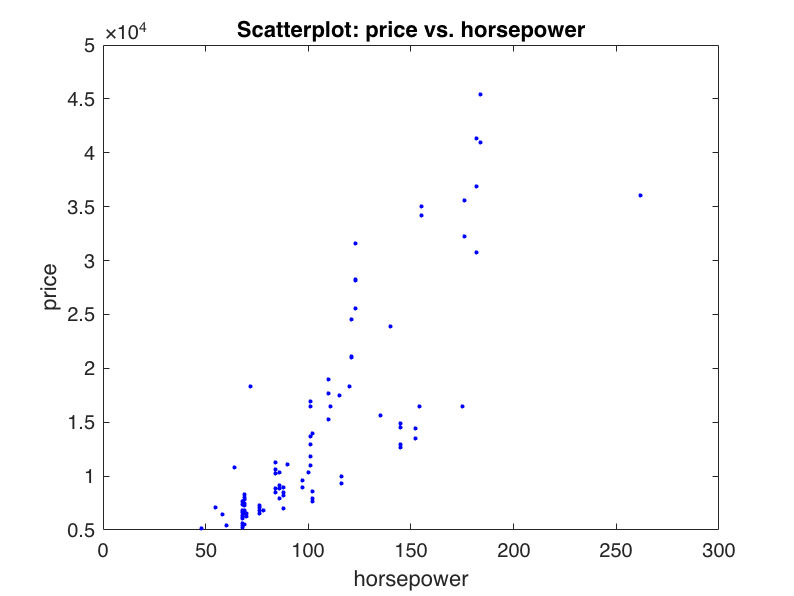

figure()
plot(horsepower,price,'b.')
xlabel('horsepower')
ylabel('price')
title('Scatterplot: price vs. horsepower')

## Task 4:

Compute coefficients of the linear models that best fit the data

The best linear model that fits a model describing the following relationship between observations $x_i$, dependent variables, and $y_i$, prices:

$y_i = \beta_0 + \beta_1 x_i + \varepsilon_i$, $i = 1, \dots, m$,

where m is the number of observations in our dataset, is the one that has the optimal coefficients. So we introduce:

$\mathbf y = \left[\matrix{y_1 \cr \vdots \cr y_m}\right]$, the vector of the response variable;

$X= \left[\matrix{1 & x_1 \cr \vdots & \vdots \cr 1 & x_m}\right]$, the design matrix;

$\mathbf \beta = \left[\matrix{\beta_0 \cr \beta_1}\right]$, the vector of coefficients;

$\mathbf \varepsilon = \left[\matrix{\varepsilon_1 \cr \vdots \cr \varepsilon_m}\right]$, the vector of residuals.

Now we need to minimize the *residual sum of squares *$||\mathbf \varepsilon||^2 = ||\mathbf y - X \mathbf \beta||^2 =: f(\mathbf \beta)$.

If $X$ has linearly independent columns (i.e., $X^TX$ is invertible), then $f$ has a unique global minimum point $\hat \mathbf \beta$, which gives us the coefficients of *the* best linear model fitting the data:

$\hat \mathbf \beta = (X^TX)^{-1}X^T\mathbf y$.

#### For Price-Length

ml = length(len);
Xl = [ones(ml,1) len];
beta_hat_l = inv(Xl.'*Xl)*Xl.'*price

beta_hat_l = 	1.0e+04 *

   -8.7364
    0.0588


#### For Price-Curb weight

mc = length(curb_weight);
Xc = [ones(mc,1) curb_weight];
beta_hat_c = inv(Xc.'*Xc)*Xc.'*price

beta_hat_c = 	1.0e+04 *

   -2.2649
    0.0015


#### For Price-Engine size

me = length(engine_size);
Xe = [ones(me,1) engine_size];
beta_hat_e = inv(Xe.'*Xe)*Xe.'*price

beta_hat_e = 	1.0e+03 *

   -7.5565
    0.1663


#### For Price-Horsepower

mh = length(horsepower);
Xh = [ones(mh,1) horsepower];
beta_hat_h = inv(Xh.'*Xh)*Xh.'*price

beta_hat_h = 	1.0e+03 *

   -7.5679
    0.2084


## Task 5:

Plot the regression line on each of the corresponding scatterplots previously generated.

In order to do this we have re-plotted the previous scatterplot and thanks to the matlab function "hold on", we can plot the regression line "fitted_v_*" on it. But always remember to type "hold off" at the end!

#### For Price-Length

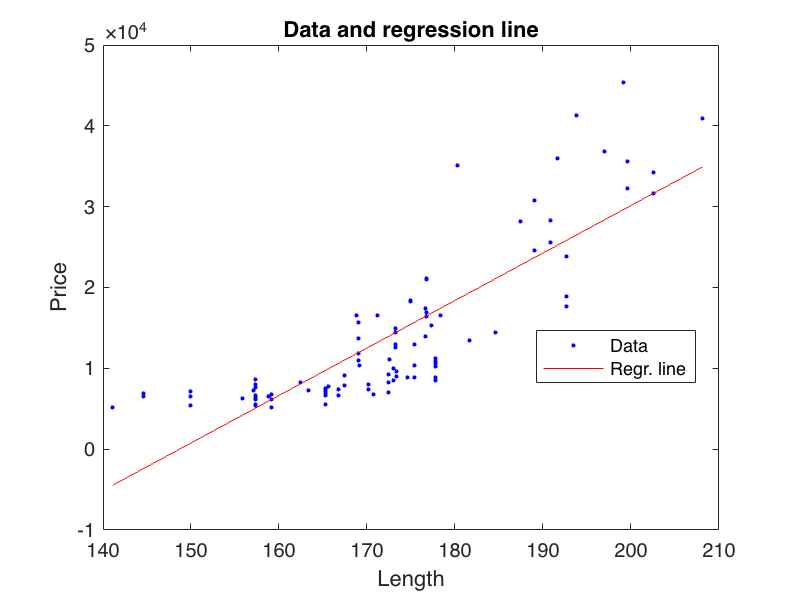

fitted_v_l = Xl*beta_hat_l;
figure()
plot(len,price,'b.','DisplayName','Data')
hold on
plot(len,fitted_v_l, 'r-', 'DisplayName','Regr. line')
xlabel('Length')
ylabel('Price')
title('Data and regression line')
legend('Location','best')
hold off

#### For Price-Curb weight

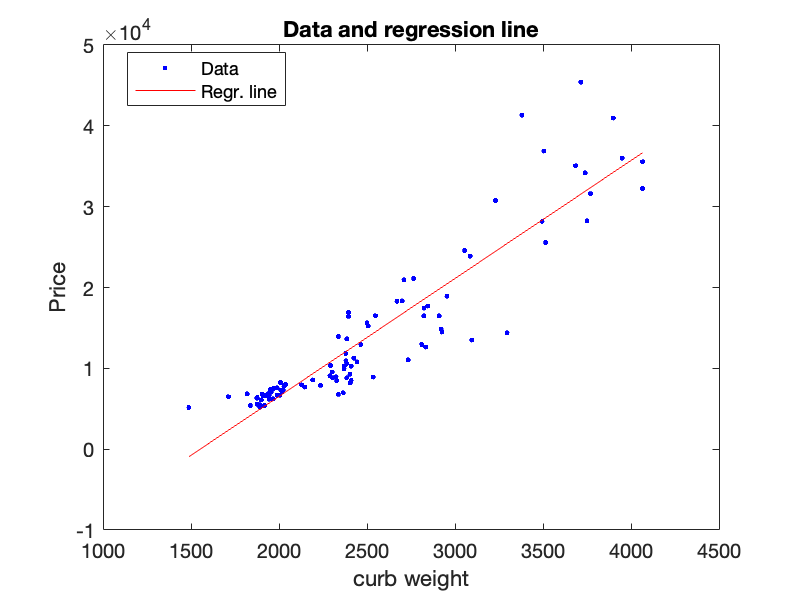

fitted_v_c = Xc*beta_hat_c;
figure()
plot(curb_weight,price,'b.','DisplayName','Data')
hold on
plot(curb_weight,fitted_v_c, 'r-', 'DisplayName','Regr. line')
xlabel('curb weight')
ylabel('Price')
title('Data and regression line')
legend('Location','best')
hold off

#### For Price-Engine size

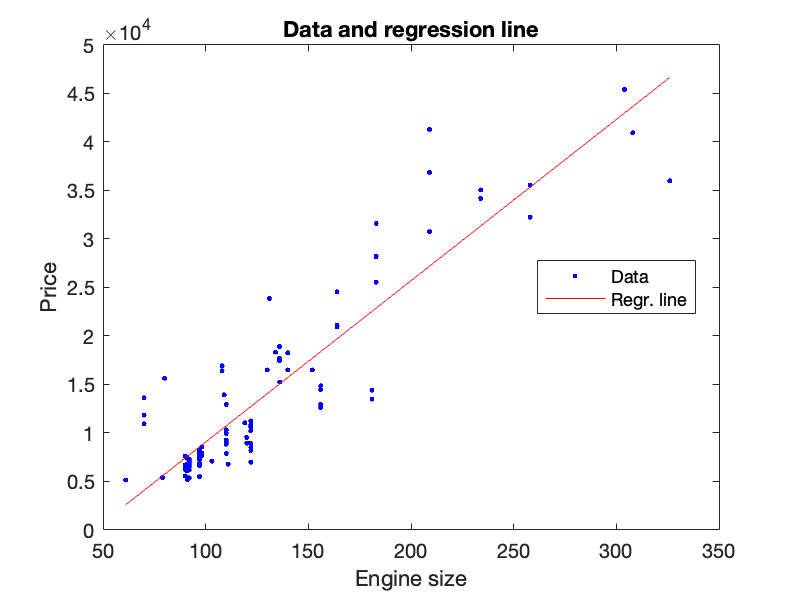

fitted_v_e = Xe*beta_hat_e;
figure()
plot(engine_size,price,'b.','DisplayName','Data')
hold on
plot(engine_size,fitted_v_e, 'r-', 'DisplayName','Regr. line')
xlabel('Engine size')
ylabel('Price')
title('Data and regression line')
legend('Location','best')
hold off

#### For Price-Horsepower

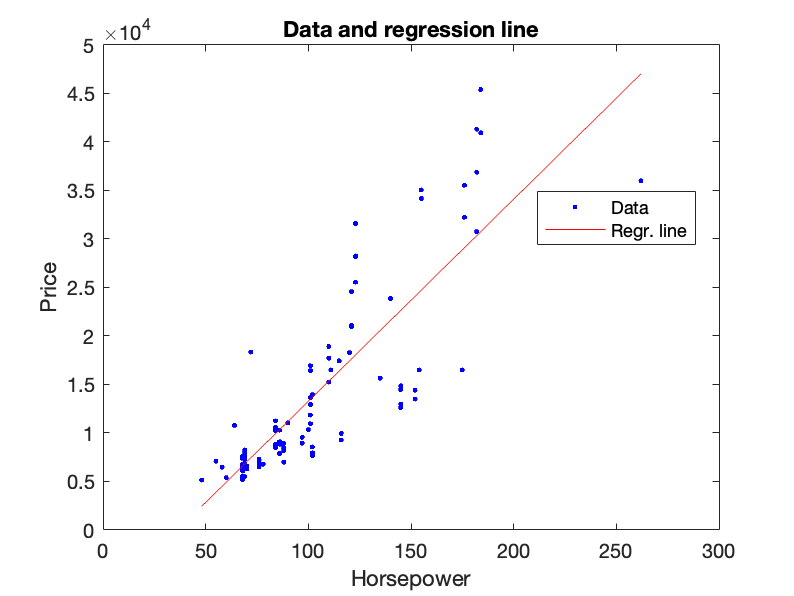

fitted_v_h = Xh*beta_hat_h;
figure()
plot(horsepower,price,'b.','DisplayName','Data')
hold on
plot(horsepower,fitted_v_h, 'r-', 'DisplayName','Regr. line')
xlabel('Horsepower')
ylabel('Price')
title('Data and regression line')
legend('Location','best')
hold off

## Task 6:

Compute in MATLAB the root mean square error (RMSE) for each of the models previously obtained. 

We can compute the residual sum of squares and the least-squares error (its square root) in order to make comparisons between models.

Calculating the *mean square error (MSE) *and the *root mean square error (RMSE) *we are accounting for the number of observations. These are defined as follows:

$\mathrm{MSE} = \frac 1m ||y - X\hat\mathbf \beta||^2 = \frac 1m ||\hat\mathbf \epsilon||^2$,


$$\mathrm{RMSE}  = \sqrt{\mathrm{MSE}} = \sqrt{\frac 1m ||\hat\mathbf \epsilon||^2}$$


#### For Price-Length

lsel = norm(price - fitted_v_l) % The least-squares error

lsel = 5.1851e+04

disp(sprintf('The least-squares error is: %.3f', lsel))

The least-squares error is: 51850.838


rssl = lsel^2 % The residual sum of squares

rssl = 2.6885e+09

disp(sprintf('The residual sum of squares is: %.3f', rssl))

The residual sum of squares is: 2688509424.912


msel = rssl/ml % The mean square error

msel = 2.7157e+07

disp(sprintf('The mean square error is: %.3f', msel))

The mean square error is: 27156660.858


rmsel = sqrt(msel) % The root mean square error

rmsel = 5.2112e+03

disp(sprintf('The root mean square error is: %.3f', rmsel))

The root mean square error is: 5211.205



mean_l = mean(len)

mean_l = 172.2768

disp(sprintf('The mean for length is: %.3f', mean_l))

The mean for length is: 172.277


analysis_l = rmsel - mean_l

analysis_l = 5.0389e+03

disp(sprintf('The difference between the value of RMSE for length and its mean is: %.3f', analysis_l))

The difference between the value of RMSE for length and its mean is: 5038.929


#### For Price-Curb weight

lsec = norm(price - fitted_v_c) % The least-squares error

lsec = 3.7416e+04

disp(sprintf('The least-squares error is: %.3f', lsec))

The least-squares error is: 37416.135


rssc = lsec^2 % The residual sum of squares

rssc = 1.4000e+09

disp(sprintf('The residual sum of squares is: %.3f', rssc))

The residual sum of squares is: 1399967192.630


msec = rssc/mc % The mean square error

msec = 1.4141e+07

disp(sprintf('The mean square error is: %.3f', msec))

The mean square error is: 14141082.754


rmsec = sqrt(msec) % The root mean square error

rmsec = 3.7605e+03

disp(sprintf('The root mean square error is: %.3f', rmsec))

The root mean square error is: 3760.463



mean_cw = mean(curb_weight)

mean_cw = 2.5021e+03

disp(sprintf('The mean for curb weight is: %.3f', mean_cw))

The mean for curb weight is: 2502.101


analysis_cw = rmsec - mean_cw

analysis_cw = 1.2584e+03

disp(sprintf('The difference between the value of RMSE for curb weight and its mean is: %.3f', analysis_cw))

The difference between the value of RMSE for curb weight and its mean is: 1258.362


#### For Price-Engine Size

lsee = norm(price - fitted_v_e) % The least-squares error

lsee = 4.0869e+04

disp(sprintf('The least-squares error is: %.3f', lsee))

The least-squares error is: 40869.095


rsse = lsee^2 % The residual sum of squares

rsse = 1.6703e+09

disp(sprintf('The residual sum of squares is: %.3f', rsse))

The residual sum of squares is: 1670282905.575


msee = rsse/me % The mean square error

msee = 1.6872e+07

disp(sprintf('The mean square error is: %.3f', msee))

The mean square error is: 16871544.501


rmsee = sqrt(msee) % The root mean square error

rmsee = 4.1075e+03

disp(sprintf('The root mean square error is: %.3f', rmsee))

The root mean square error is: 4107.499



mean_es = mean(engine_size)

mean_es = 128.7677

disp(sprintf('The mean for curb weight is: %.3f', mean_es))

The mean for curb weight is: 128.768


analysis_es = rmsee - mean_es

analysis_es = 3.9787e+03

disp(sprintf('The difference between the value of RMSE for engine size and its mean is: %.3f', analysis_es))

The difference between the value of RMSE for engine size and its mean is: 3978.731


#### For Price-Horsepower

lseh = norm(price - fitted_v_h) % The least-squares error

lseh = 5.2037e+04

disp(sprintf('The least-squares error is: %.3f', lseh))

The least-squares error is: 52037.339


rssh = lseh^2 % The residual sum of squares

rssh = 2.7079e+09

disp(sprintf('The residual sum of squares is: %.3f', rssh))

The residual sum of squares is: 2707884613.802


mseh = rssh/mh % The mean square error

mseh = 2.7352e+07

disp(sprintf('The mean square error is: %.3f', mseh))

The mean square error is: 27352369.836


rmseh = sqrt(mseh) % The root mean square error

rmseh = 5.2299e+03

disp(sprintf('The root mean square error is: %.3f', rmseh))

The root mean square error is: 5229.949



mean_h = mean(horsepower)

mean_h = 102.8182

disp(sprintf('The mean for curb weight is: %.3f', mean_h))

The mean for curb weight is: 102.818


analysis_h = rmseh - mean_h

analysis_h = 5.1271e+03

disp(sprintf('The difference between the value of RMSE for horsepower and its mean is: %.3f', analysis_h))

The difference between the value of RMSE for horsepower and its mean is: 5127.131


## Task 7:

Try to use the linear models obtained to make some predictions using possible new observations of the regressors.

This problem is interesting as we know that if we choose new observations far away from the range of the range of our independent variable, the prediction would not be so reliable. On the other hand, if the new values fall inside our range the prediction will be much more trustable.

We have decided to solve this problem taking into account the model Price vs Length. We start by looking for our range thanks to the min and max functions. Then we put some random values and we predict them.

min(len)

ans = 141.1000

max(len)

ans = 208.1000

len_new = [108 143 188 200 207].'

len_new =    108
   143
   188
   200
   207


ml_new = length(len_new);
Xl_new = [ones(ml_new,1) len_new];
pred_price = Xl_new*beta_hat_l;
disp('For the new observations we obtain the following predictions:')

For the new observations we obtain the following predictions:


disp('     1         2         3         4         5')

     1         2         3         4         5


disp(pred_price.')

   1.0e+04 *

   -2.3910   -0.3346    2.3093    3.0143    3.4256



The we have decided to plot it in order to visualize predictions better. From the graph we can notice that our new observations are falling a lot near the regression line.

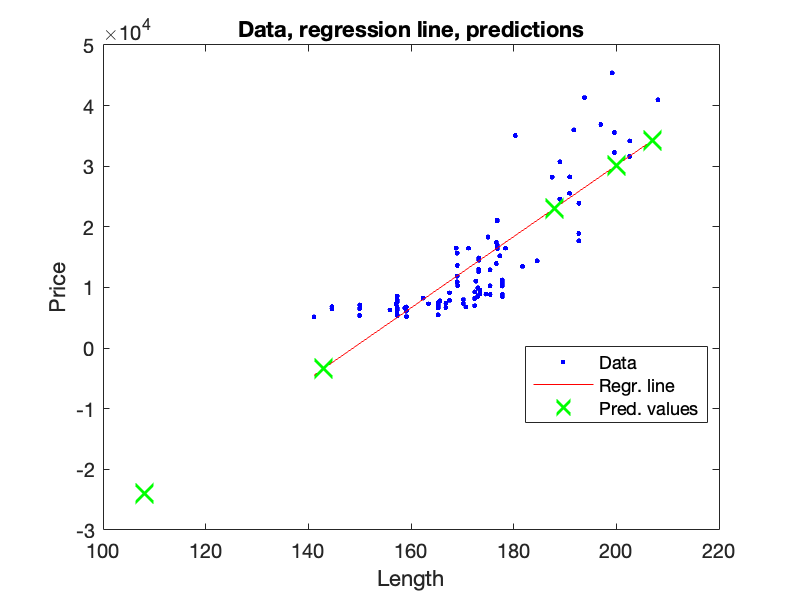

figure()
plot(len,price,'b.','DisplayName','Data')
hold on
plot(len,fitted_v_l, 'r-', 'DisplayName','Regr. line')
plot(len_new,pred_price, 'gx','MarkerSize',10,'LineWidth',2,'DisplayName', 'Pred. values')
xlabel('Length')
ylabel('Price')
title('Data, regression line, predictions')
legend('Location','best')
hold off

#### Price-curb weight 

min(curb_weight)

ans = 1488

max(curb_weight)

ans = 4066

curb_new = [1500 2651 2999 3701 4065].'

curb_new =         1500
        2651
        2999
        3701
        4065


mc_new = length(curb_new);
Xc_new = [ones(mc_new,1) curb_new];
pred_price = Xc_new*beta_hat_c;
disp('For the new observations we obtain the following predictions:')

For the new observations we obtain the following predictions:


disp('     1         2         3         4         5')

     1         2         3         4         5


disp(pred_price.')

   1.0e+04 *

   -0.0765    1.6027    2.1104    3.1346    3.6656



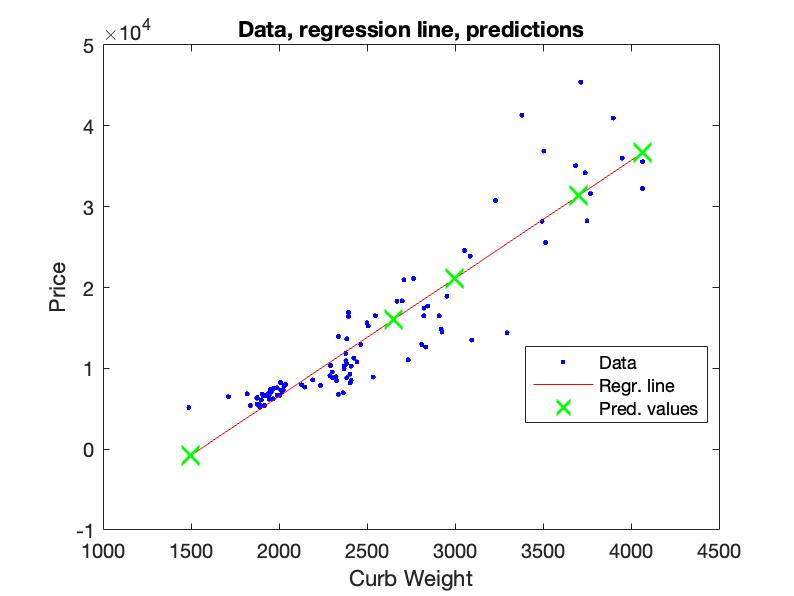


figure()
plot(curb_weight,price,'b.','DisplayName','Data')
hold on
plot(curb_weight,fitted_v_c, 'r-', 'DisplayName','Regr. line')
plot(curb_new,pred_price, 'gx','MarkerSize',10,'LineWidth',2,'DisplayName', 'Pred. values')
xlabel('Curb Weight')
ylabel('Price')
title('Data, regression line, predictions')
legend('Location','best')
hold off

#### Price-engine size

min(engine_size)

ans = 61

max(engine_size)

ans = 326

engine_new = [50 61 167 224 300].'

engine_new =     50
    61
   167
   224
   300


me_new = length(engine_new);
Xe_new = [ones(me_new,1) engine_new];
pred_price = Xe_new*beta_hat_e;
disp('For the new observations we obtain the following predictions:')

For the new observations we obtain the following predictions:


disp('     1         2         3         4         5')

     1         2         3         4         5


disp(pred_price.')

   1.0e+04 *

    0.0757    0.2586    2.0212    2.9690    4.2327



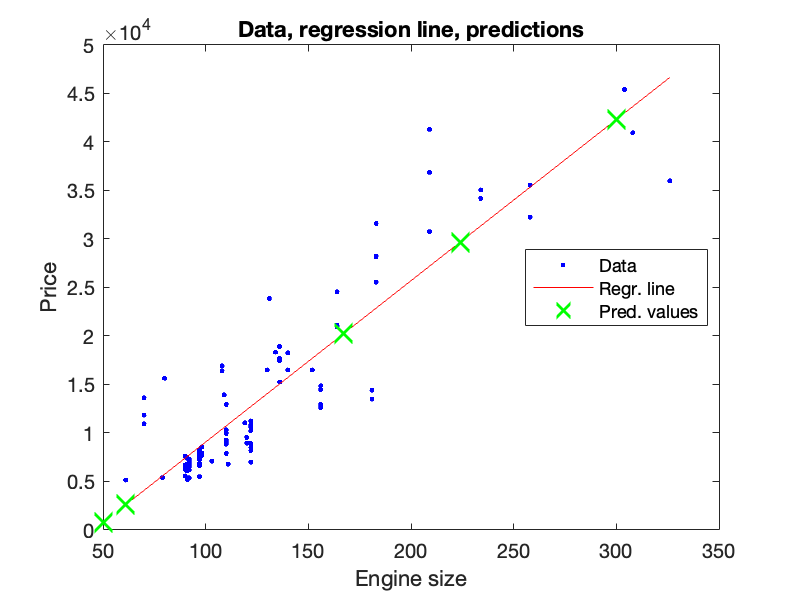


figure()
plot(engine_size,price,'b.','DisplayName','Data')
hold on
plot(engine_size,fitted_v_e, 'r-', 'DisplayName','Regr. line')
plot(engine_new,pred_price, 'gx','MarkerSize',10,'LineWidth',2,'DisplayName', 'Pred. values')
xlabel('Engine size')
ylabel('Price')
title('Data, regression line, predictions')
legend('Location','best')
hold off

#### Price-horsepower

min(horsepower)

ans = 48

max(horsepower)

ans = 262

h_new = [10 50 120 200 1000].'

h_new =           10
          50
         120
         200
        1000


mh_new = length(h_new);
Xh_new = [ones(mh_new,1) h_new];
pred_price = Xh_new*beta_hat_h;
disp('For the new observations we obtain the following predictions:')

For the new observations we obtain the following predictions:


disp('     1         2         3         4         5')

     1         2         3         4         5


disp(pred_price.')

   1.0e+05 *

   -0.0548    0.0285    0.1743    0.3410    2.0079



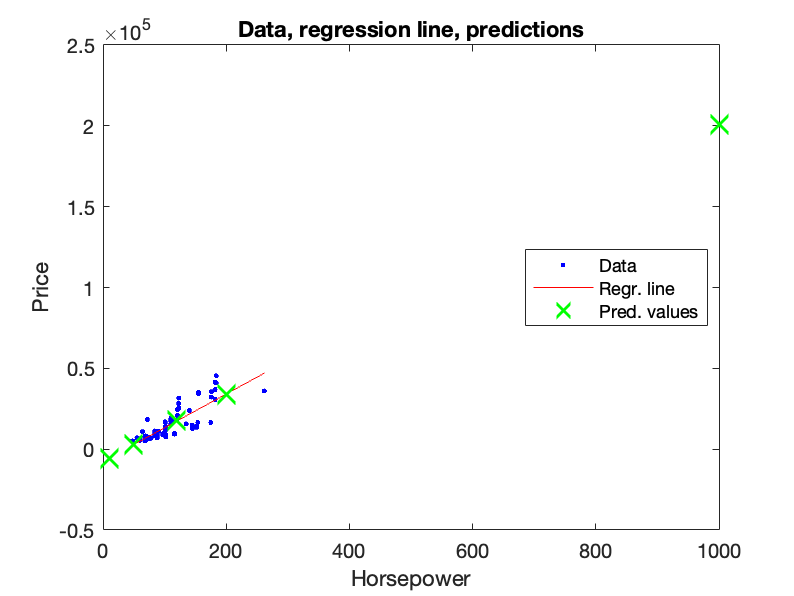


figure()
plot(horsepower,price,'b.','DisplayName','Data')
hold on
plot(horsepower,fitted_v_h, 'r-', 'DisplayName','Regr. line')
plot(h_new,pred_price, 'gx','MarkerSize',10,'LineWidth',2,'DisplayName', 'Pred. values')
xlabel('Horsepower')
ylabel('Price')
title('Data, regression line, predictions')
legend('Location','best')
hold off

# **MATLAB PROJECT: SECOND PART**

## **Task 1:**

We insert our data into variables as follows:

pred_var = Automobiledata(:,1:4);
y = Automobiledata(:,5);

In order to observe the relationship between each one of the prdictors and the independent variable, we can plot our data using four scatterplots as we have done in the first part of the project.

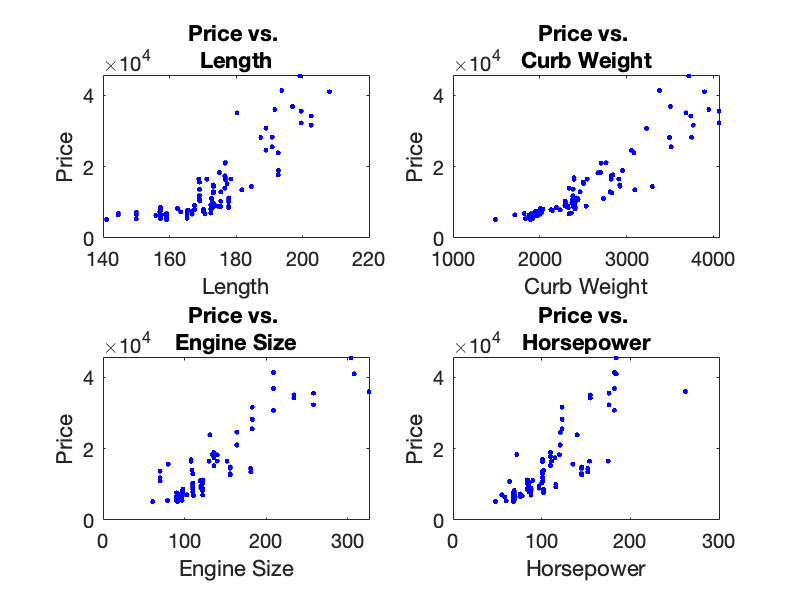

labels = ["Length" "Curb Weight" "Engine Size" "Horsepower" "Price"];
figure()
for(i=1:4)
    subplot(2,2,i)
    plot(pred_var(:,i),y,'b.')
    title(['Price vs. ' labels(i)])
    xlabel(labels(i))
    ylabel('Price')
end
hold off

As we had already noticed, we can remark that all the models seem to have an approximately linear relationship between the variables, except the one for Price and Length which has a either linear or quadratic relationship.

In general, what we have done until know does not give us a complete vision of the analysis so we are going to build a model considering all the four variables together.

We now try to determine the best linear model that fits the data, among those who satisfy:

$P_i = \beta_0 + \beta_1 \ell_i + \beta_2 w_i + \beta_3 s_i + \beta_4 h_i + \varepsilon_i$, $i = 1, \dots, m$,

where $m = 100$ and $\ell_i$, $w_i$, $s_i$, $h_i$, $P_i$, refer to the length, curb weight, engine size, horsepower, and price of the automobile, respectively.

To find the optimal coefficients of such a model we introduce:

$\mathbf y = \left[\matrix{P_1 \cr \vdots \cr P_m}\right]$, the vector of the response variable;

$X= \left[\matrix{1 & \ell_1 & w_1 & s_1 & h_1 \cr \vdots & \vdots &\vdots & \vdots & \vdots \cr 1 & \ell_m & w_m & s_m & h_m}\right]$, the design matrix;

$\mathbf \beta = \left[\matrix{\beta_0 \cr \beta_1 \cr \beta_2 \cr \beta_3 \cr \beta_4}\right]$, the vector of coefficients;

$\mathbf \varepsilon = \left[\matrix{\varepsilon_1 \cr \vdots \cr \varepsilon_m}\right]$, the vector of residuals.

From lectures, we know that we need to minimize the *residual sum of squares *$||\mathbf \varepsilon||^2 = ||\mathbf y - X \mathbf \beta||^2 =: f(\mathbf \beta)$,

that is, to find $\mathbf \beta$ that minimizes the distance between $\mathbf y$ and $X\mathbf \beta$ that can be done by solving the linear system $\mathbf y = X\mathbf \beta$ in the least-squares sense which, in turn, is equivalent to solving the normal equation

$X^TX \mathbf \beta = X^T \mathbf y$.

If $X$ has linearly independent columns (i.e., $X^TX$ is invertible), then *the* best linear model fitting the data has coefficients:

$\hat \mathbf \beta = (X^TX)^{-1}X^T\mathbf y$.

Luckily, in MATLAB it is much more easy to compute solutions to linear systems, both in the classical sense and in the least-squares sense, *via* the *backslash operator *`\`. Let's see how to do it:

m = length(y);
X = [ones(m,1) pred_var];
beta_hat = X\y

beta_hat = 	1.0e+04 *

   -2.5974
    0.0070
    0.0007
    0.0068
    0.0015


## Task 2

We can notice that all values are pretty near to zero, except for the $\beta_0 $, which is negative. We expected this coefficient to be strictly positive as it is the interception with the t-axis (price). While all the other coefficients, as we know from simple linear regression, are the slopes of the relationship, which is obviously linear, between the response variable and the predictor variable, independently from the others.

Unluckily, having a multi linear regression case implies that we cannot represent graphically our results. 

## Task 3:

Since we are studying the automobiles, we can build other models that have as independent variables that have a stronger linear dependence with Price, which are all, except for Lenght and Horsepower.

- Curb-weight, engine size

## Task 4:

%extracting the predictors of interest
predictors1 = Automobiledata(:, [2,3]);

% creating the design matrix
X_1 = [ones(m,1) predictors1];
beta_hat_1 = X_1\y

beta_hat_1 = 	1.0e+04 *

   -1.7848
    0.0009
    0.0070


But, as we have already said, we cannot represent them graphically since the model takes into account multiple dimensions.

## Task 5:

As we have previously noticed, not all models give us a linear relationship, as in the case of Length-Price, it seems to be linear or quadratic. 

This is why we can try the data fitting, that is the process of constructing a curve that best fits our series of data points, possibly subject to constraints. 

In our case, looking at the graph, we can try a polynomial fitting for the model Length-Price. 

This polynomial pattern, geometrically, lets the data points near to the curve:

$y_i = \beta_0 + \beta_1 t_i + \beta_2 t_i^2 + \beta_3 t_i^3 + \epsilon_i, \, i=1,\dots,m$,

## Task 6:

% extracting the predictor variable
mx = Automobiledata(:,[1 5])

mx = 	1.0e+04 *

    0.0169    1.6500
    0.0171    1.6500
    0.0177    1.3950
    0.0177    1.7450
    0.0177    1.5250
    0.0193    1.7710
    0.0193    1.8920
    0.0193    2.3875
    0.0177    1.6430
    0.0177    1.6925


mx = sortrows(mx, 1)

mx = 	1.0e+04 *

    0.0141    0.5151
    0.0145    0.6479
    0.0145    0.6855
    0.0150    0.5399
    0.0150    0.6529
    0.0150    0.7129
    0.0156    0.6295
    0.0157    0.7295
    0.0157    0.5572
    0.0157    0.6377


sorted_len = mx(:,1)

sorted_len =   141.1000
  144.6000
  144.6000
  150.0000
  150.0000
  150.0000
  155.9000
  157.1000
  157.3000
  157.3000


sorted_price = mx (: ,2)

sorted_price =         5151
        6479
        6855
        5399
        6529
        7129
        6295
        7295
        5572
        6377



m = length(sorted_len);
X_ll = [ones(m,1) sorted_len sorted_len.^2];
beta_hat_ll = X_ll\sorted_price

beta_hat_ll = 	1.0e+05 *

    2.6183
   -0.0344
    0.0001


## Task 7:

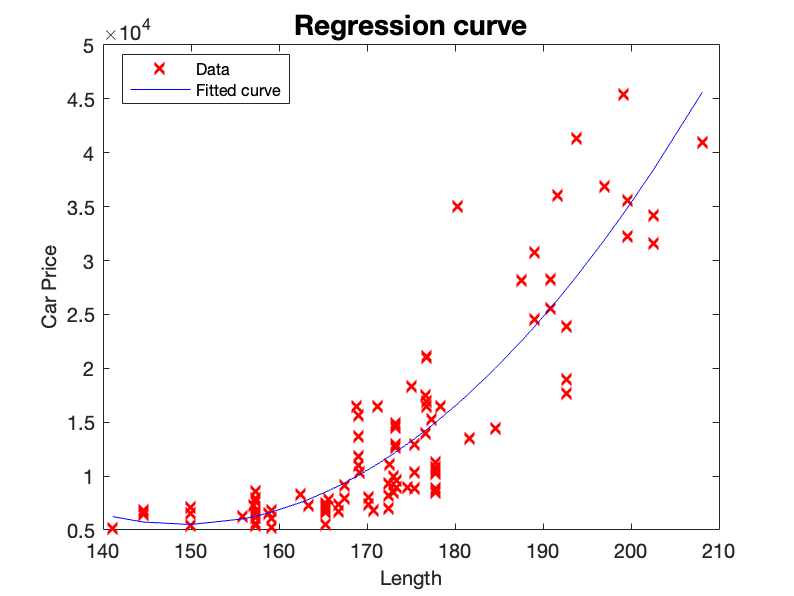

fitted_ll = X_ll*beta_hat_ll;
figure()
plot(sorted_len,sorted_price,'rx','MarkerSize',6,'LineWidth',2)
title('Regression curve','FontSize',14)
xlabel('Length','FontSize',10)
ylabel('Car Price','FontSize',10)
hold on
plot(sorted_len,fitted_ll,'b-')
legend('Data','Fitted curve','FontSize',8,'Location','best')
hold off

## Task 8:

For what regards the polynomial model, we can notice that the interception with the y-axis is strictly positive, so we can probably trust these results. In particular, about the coefficients we say that:

- $\beta_0$: gives the estimated initial price of the automobiles;

- $\beta_1$: gives the rate of the change of price with respect to length (for instance, if the length of the car increases by 1, the price of the car increases by $\beta_1$)

- $\beta_2$: the longer the car, the greater the increment of price;

## Task 9:

**RMSE for the model considering all the predictors:**

fitted_all = X*beta_hat; % Fitted values
lse_all = norm(y - fitted_all) % The least-squares error

lse_all = 3.4103e+04

disp(sprintf('The least-squares error is: %.3f', lse_all))

The least-squares error is: 34103.184


rss_all = lse_all^2 % The residual sum of squares

rss_all = 1.1630e+09

disp(sprintf('The residual sum of squares is: %.3f', rss_all))

The residual sum of squares is: 1163027140.875


mse_all = rss_all/m % The mean square error

mse_all = 1.1748e+07

disp(sprintf('The mean square error is: %.3f', mse_all))

The mean square error is: 11747748.898


rmse_all = sqrt(mse_all) % The root mean square error

rmse_all = 3.4275e+03

disp(sprintf('The root mean square error is: %.3f', rmse_all))

The root mean square error is: 3427.499


**RMSE for the model (Curb-weight, engine size)-price:**

fitted_1 = X_1*beta_hat_1; % Fitted values
lse_1 = norm(y - fitted_1) % The least-squares error

lse_1 = 3.4387e+04

disp(sprintf('The least-squares error is: %.3f', lse_1))

The least-squares error is: 34387.274


rss_1 = lse_1^2 % The residual sum of squares

rss_1 = 1.1825e+09

disp(sprintf('The residual sum of squares is: %.3f', rss_1))

The residual sum of squares is: 1182484640.596


mse_1 = rss_1/m % The mean square error

mse_1 = 1.1944e+07

disp(sprintf('The mean square error is: %.3f', mse_1))

The mean square error is: 11944289.299


rmse_1 = sqrt(mse_1) % The root mean square error

rmse_1 = 3.4561e+03

disp(sprintf('The root mean square error is: %.3f', rmse_1))

The root mean square error is: 3456.051


**RMSE for the polynomia model :**

fitted_p = X_ll*beta_hat_ll; % Fitted values
lse_p = norm(y - fitted_p) % The least-squares error

lse_p = 1.3922e+05

disp(sprintf('The least-squares error is: %.3f', lse_p))

The least-squares error is: 139224.735


rss_p = lse_p^2 % The residual sum of squares

rss_p = 1.9384e+10

disp(sprintf('The residual sum of squares is: %.3f', rss_p))

The residual sum of squares is: 19383526737.219


mse_p = rss_p/m % The mean square error

mse_p = 1.9579e+08

disp(sprintf('The mean square error is: %.3f', mse_p))

The mean square error is: 195793199.366


rmse_p = sqrt(mse_p) % The root mean square error

rmse_p = 1.3993e+04

disp(sprintf('The root mean square error is: %.3f', rmse_p))

The root mean square error is: 13992.612


# **MATLAB PROJECT: THIRD PART**

## **Task 1:**

We insert all our independent variables inside the variable 'all'. Then, we compute the eigenvalues and eigenverctors of our squared matrix. An **eigenvector** is a nonzero vector that changes at most by a scalar factor when that linear transformation is applied to it. The corresponding **eigenvalue**, often denoted by $\lambda$, is the factor by which the eigenvector is scaled.

all = Automobiledata(:,[1,2,3,4])

all = 	1.0e+03 *

    0.1688    2.5480    0.1300    0.1110
    0.1712    2.8230    0.1520    0.1540
    0.1766    2.3370    0.1090    0.1020
    0.1766    2.8240    0.1360    0.1150
    0.1773    2.5070    0.1360    0.1100
    0.1927    2.8440    0.1360    0.1100
    0.1927    2.9540    0.1360    0.1100
    0.1927    3.0860    0.1310    0.1400
    0.1768    2.3950    0.1080    0.1010
    0.1768    2.3950    0.1080    0.1010


s = corrcoef(all)

s =     1.0000    0.9020    0.8087    0.7413
    0.9020    1.0000    0.9143    0.8761
    0.8087    0.9143    1.0000    0.8633
    0.7413    0.8761    0.8633    1.0000


[m,n] = size(all)

m = 99

n = 4

[P,D]= eig(s,'vector') %option vector puts eigenvalues into a vector, rather then a diagonal matrix

P =    -0.3954    0.2475    0.7396    0.4852
    0.8469   -0.0019    0.1124    0.5197
   -0.2824   -0.7857   -0.2192    0.5049
   -0.2160    0.5669   -0.6264    0.4895


D =     0.0506
    0.1244
    0.2696
    3.5554


## **Task 2:**

Here, we determine the proportion of total sample variance.

We first need to sort eigenvalues in descending order to associate the first component to the highest eigenvalue and so on.

eigval_cor = sort(D,'descend')

eigval_cor =     3.5554
    0.2696
    0.1244
    0.0506


totalvar_cor = sum(eigval_cor)

totalvar_cor = 4

prop_cor = eigval_cor./totalvar_cor;       

And here we plot the scree plot. It is a plot of the eigenvalues of factors or principal components in an analysis. The scree plot is used to determine the number of principal components to keep in a principal component analysis (PCA).

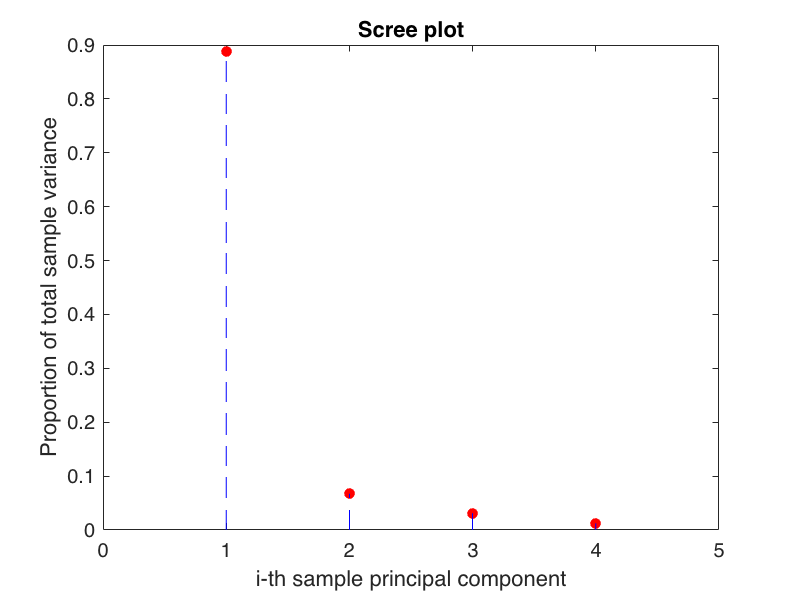

figure();
plot([1:n],prop_cor,'r.','MarkerSize',16)
xlim([0 n+1]);
hold on
for k = 1:n
    N = 100;
    x = k*ones(N);
    y = linspace(0,prop_cor(k),N);
    plot(x,y,'b--')
end
xlabel('i-th sample principal component')
ylabel('Proportion of total sample variance')
title('Scree plot')
hold off

Let $\lambda_1 \ge \lambda_2 \ge \cdots \ge \lambda_n >0$ be the eigenvalues of the sample variance matrix. From lecture we know that the total sample variance equals $\sum_{j=1}^n \lambda_j$ and that the proportion of total sample variance is:

                                             
$$\frac{\lambda_j }{\lambda_1 +\cdots +\lambda_n },~~j=1,\dots ,n\ldotp$$


In our scree plot:

- On the x-axis we put a label for each eigenvalue;

- On the y-axis we visualize the proportion of total sample variance explained by the -th principal component.

## Task 3:

In this task, we want to get the cumulative proportion plot of the total sample variance. Proportion of variance is a normalized version of the eigenvalues. This curve displays the specific proportion of the total variance explained by each principal component.

cumul_cor = cumsum(eigval_cor);         
cumulprop_cor = cumul_cor./totalvar_cor;

The line represents the cumulative proportion of sample variance explained by all the principal components. Anyway, we have noticed that taking only the first principal component we reach almost 90% of variability.

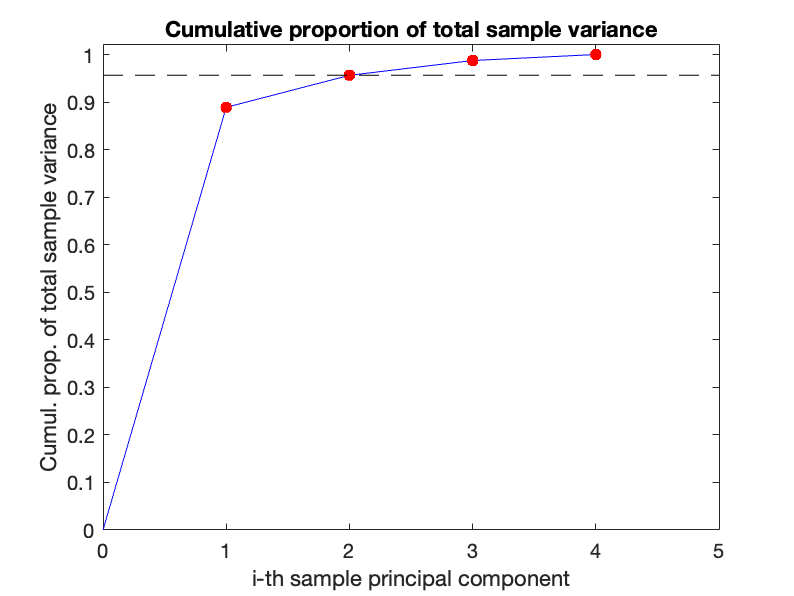

plot([0:n],[0; cumulprop_cor], 'b-')
hold on
plot([1:n],cumulprop_cor,'r.','MarkerSize',16)
xlim([0 n+1])
ylim([0 1.02])
plot(linspace(0,n+1,100),cumulprop_cor(2)*ones(100),'k--') 
xlabel('i-th sample principal component')
ylabel('Cumul. prop. of total sample variance')
title('Cumulative proportion of total sample variance')

We obtain:

disp(sprintf('The first sample principal component explains %.3f%% of variability', 100*cumulprop_cor(1)))

The first sample principal component explains 88.886% of variability


for(i=2:n)
    disp(sprintf('The first %d sample principal components explain %.3f%% of variability', i, 100*cumulprop_cor(i)))
end

The first 2 sample principal components explain 95.625% of variability
The first 3 sample principal components explain 98.736% of variability
The first 4 sample principal components explain 100.000% of variability


## Task 4:

The loading of each sample principle component is the coefficient of the linear combination of a single variable in our dataset. 

The loadings represent the coordinates of the corresponding eigenvector of the sample variance matrix and they can be interpreted as the weights that each variable in the dataset has in the sample principal component.

To get the loadings in the correct form, we need to reverse the order of the columns of the matrix P.

for i = 1:n
    loadings_corr(:,i) = P(:,end-i+1);
end

The loadings of the first principal component are:

loadings_corr(:,1)

ans =     0.4852
    0.5197
    0.5049
    0.4895


The first principal component is: ${\mathbf{y}}_1 =0\ldotp 48{\mathbf{x}}_1 +0\ldotp 52{\mathbf{x}}_2 +0\ldotp 50{\mathbf{x}}_3 +0\ldotp 49{\mathbf{x}}_4$

The coefficients of the loading are a kind of weighted average of the variables in the dataset. It can be interpreted as the structural* components* of the car.

loadings_corr(:,2)

ans =     0.7396
    0.1124
   -0.2192
   -0.6264


The second principal components captures the* elements component *and it is: ${\mathbf{y}}_2 =0\ldotp 74{\mathbf{x}}_1 +0\ldotp 11{\mathbf{x}}_2 -0\ldotp 22{\mathbf{x}}_3 -0\ldotp 63{\mathbf{x}}_4$

In this case, we can see that two out of the four coefficients are negative. We can notice a contrast between a weighted average of the variables corresponding to the physical characteristics of the car and a weighted average of the variables corresponding to the engine of a car.

## Task 5

Observations in the principal components are called scores.

By using the build-in function *diag, *we extract the diagonal elements of the sample matrix, then we take the square root. Doing this we are able to obtain sample standard deviations.

avg = mean(all)

avg = 	1.0e+03 *

    0.1723    2.5021    0.1288    0.1028


dev_std = sqrt(diag(s));
for i = 1:m
    data_std(i,:) = (all(i,:) - avg)./dev_std';
end
scores = data_std*loadings_corr;

## Task 6:

We plot the scores in the plane generated by the first two eigenvectors.

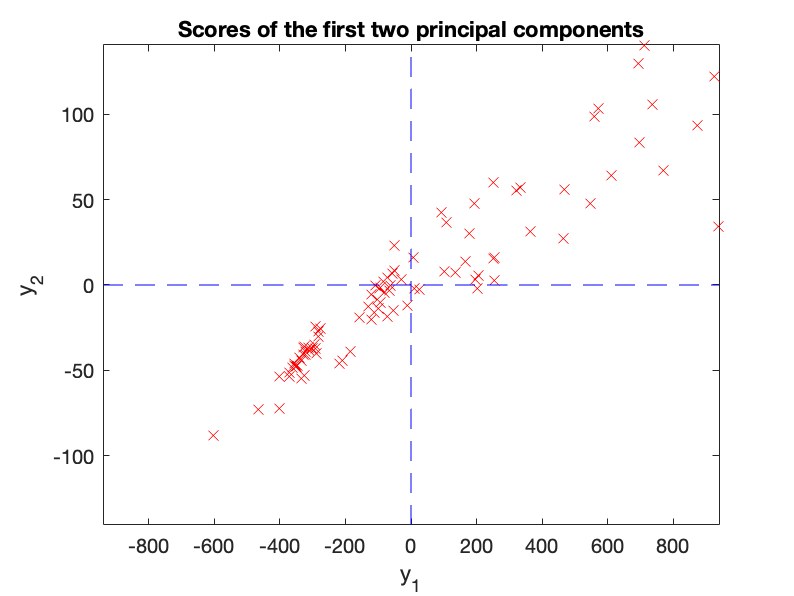

figure()
plot(scores(:,1), scores(:,2),'rx')
eps = 0.01;
xmax = max(abs(scores(:,1))) + eps; % Values to set the ranges of the axes. Add
ymax = max(abs(scores(:,2))) + eps; % eps to have some margin.
xlim([-xmax xmax])
ylim([-ymax ymax])
hold on
N = 100;
x = linspace(-xmax, xmax, N); 
y = linspace(-ymax, ymax, N);
plot(x,zeros(N),'b--')
plot(zeros(N),y,'b--')
xlabel('y_1')
ylabel('y_2')
title('Scores of the first two principal components')